## МИУ СFIE

Программа E-поляризация МВИ СFIE для цилиндра квадратного сечения

02_03_21

close all;
clear variables;

#### Входные данные 

% Пример использования:
as = 11;
phi_grad = 25;
N = 400;
alpha = 0.5;
etta = 120*pi;

## **********1. E - поляризация****************

#### 1.1. Генерация EFIE с помощью класса

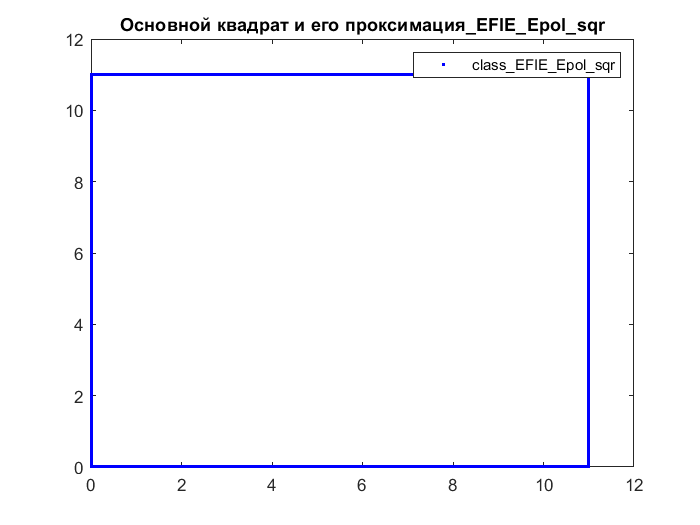

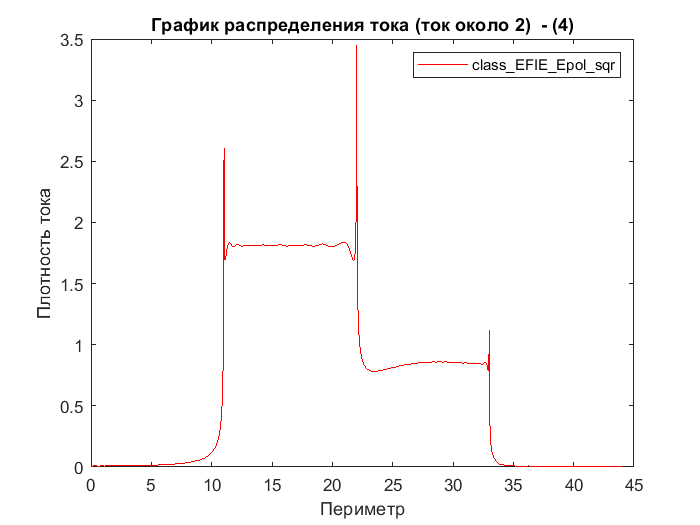

calc_1 = D_class_MIE_EFIE_sqr_E_pol(as,phi_grad);
calc_1.calculate_main_sqr(N);
calc_1.calculate_I();

Epol_EFIE_Zmn = calc_1.Zmn;
Epol_EFIE_Ei = calc_1.Ei;
Epol_EFIE_I = Epol_EFIE_Zmn\Epol_EFIE_Ei;


#### 1.2. Генерация MFIE с помощью класса

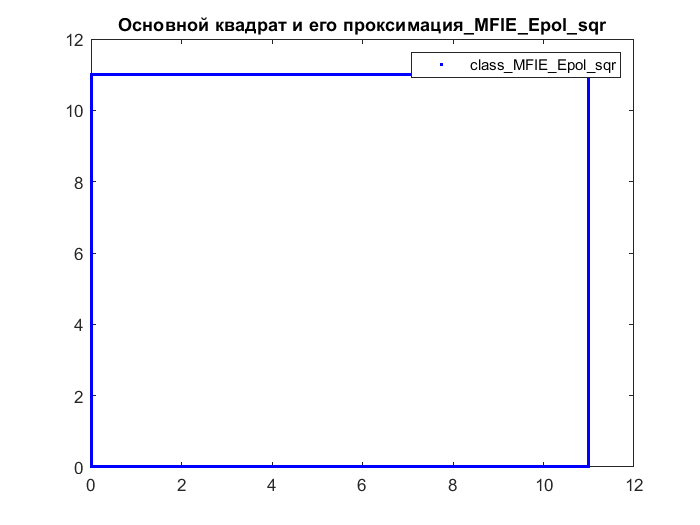

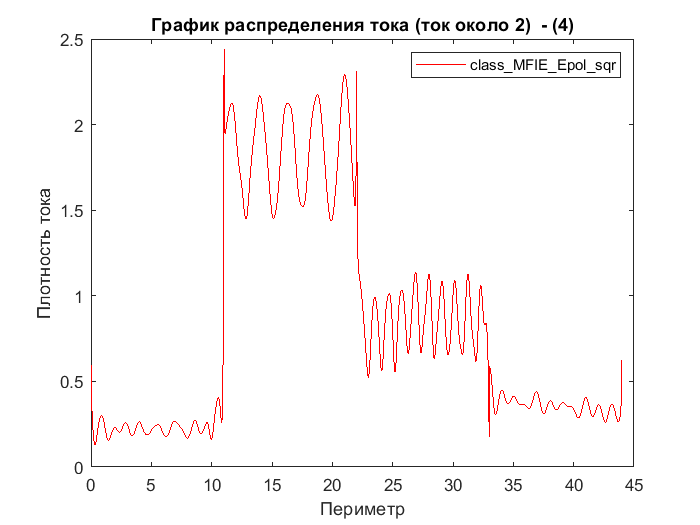

calc_2 = D_class_MIE_MFIE_sqr_E_pol(as,phi_grad);
calc_2.calculate_main_sqr(N);
calc_2.calculate_I();

Epol_MFIE_Zmn = calc_2.Zmn;
Epol_MFIE_Hi = calc_2.Hi;
Epol_MFIE_I = Epol_MFIE_Zmn\Epol_MFIE_Hi;

#### 1.3. Графики токов (где по оси НОМЕР участка)

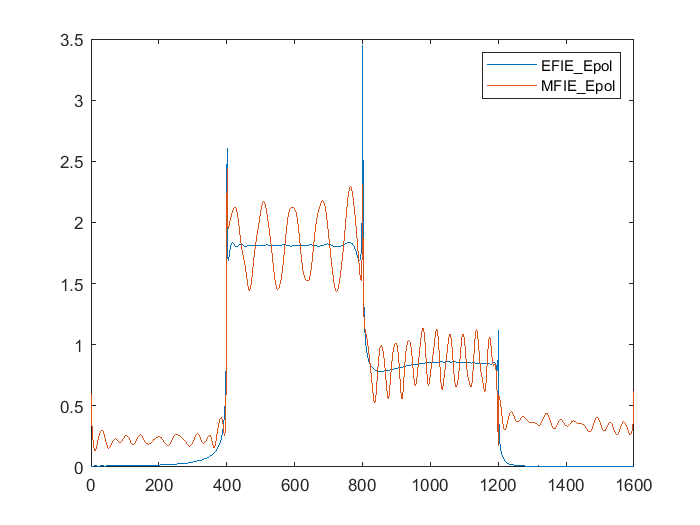

n = 1 : length(Epol_EFIE_I);
plot(n, abs(Epol_EFIE_I), n, abs(Epol_MFIE_I))
legend('EFIE\_Epol', 'MFIE\_Epol')

#### 1.4. Вычисление CFIE

В гибсоне написано делать таок:

CFIE_Zmn = alpha*EFIE_Zmn + (1-alpha)*etta*MFIE_Zmn;

CFIE_Ei = alpha*EFIE_Ei + (1-alpha)*etta*MFIE_Hi;

НО, т.к. в обеих программах задано единичное электрчиеское поле, и опустил этта со стороны падающего поля то ДОМНОЖАТЬ НИ НА ЧТО НЕ НУЖНО!

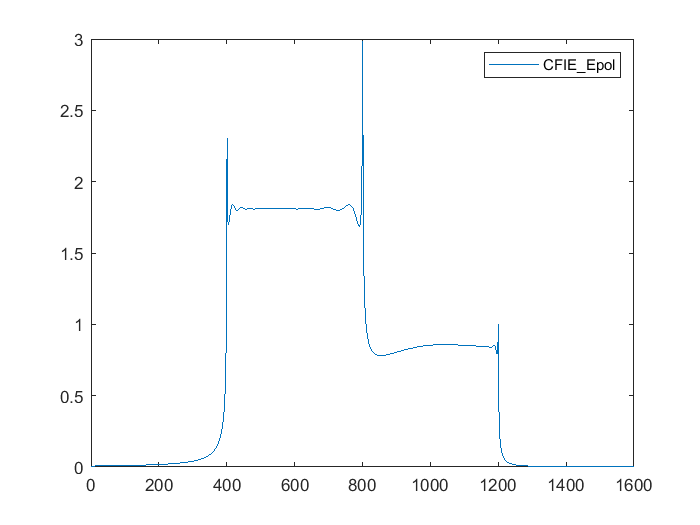

Epol_CFIE_Zmn = alpha*Epol_EFIE_Zmn + (1-alpha)*Epol_MFIE_Zmn;
Epol_CFIE_Ei = alpha*Epol_EFIE_Ei + (1-alpha)*Epol_MFIE_Hi;

Epol_CFIE_I = Epol_CFIE_Zmn\Epol_CFIE_Ei;

plot(n, abs(Epol_CFIE_I))
legend('CFIE\_Epol')

#### 1.5. Построение сравниельных графиков EFIE, MFIE, CFIE для эллипса

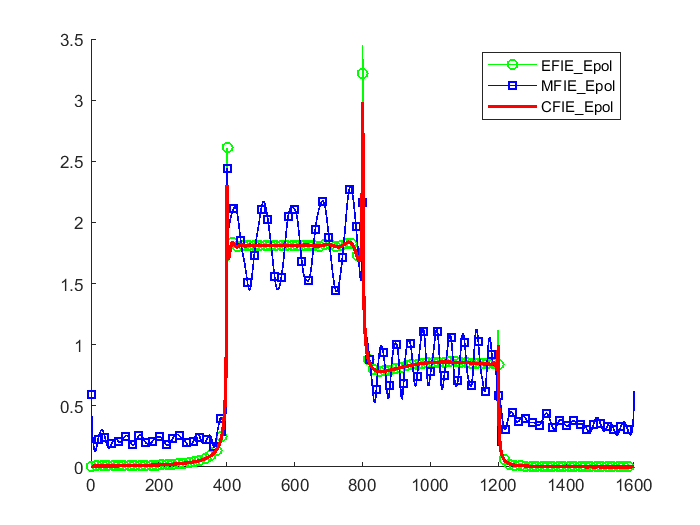

figure;
hold on;
plot(n, abs(Epol_EFIE_I),'-go', 'MarkerIndices', 1:16:length(n), 'LineWidth', 1, 'DisplayName','EFIE\_Epol')
plot(n, abs(Epol_MFIE_I),'-bs', 'MarkerIndices', 1:20:length(n),'LineWidth',1, 'DisplayName','MFIE\_Epol')
plot(n, abs(Epol_CFIE_I), 'r', 'LineWidth', 2, 'DisplayName','CFIE\_Epol')
legend;
hold off;

## **********2. H - поляризация****************

#### 2.1. Генерация EFIE с помощью класса

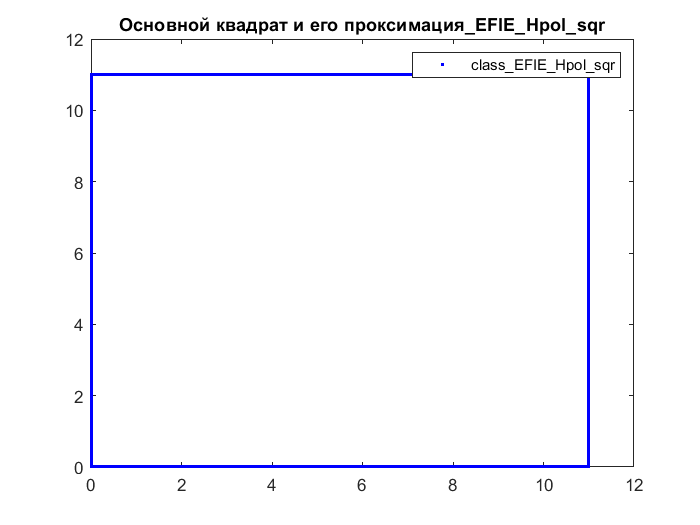

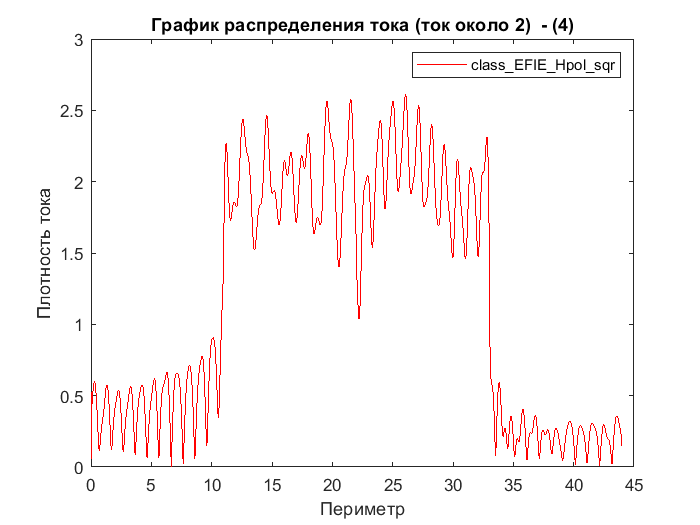

calc_3 = D_class_MIE_EFIE_sqr_H_pol(as, phi_grad);
calc_3.calculate_main_sqr(N);
calc_3.calculate_I();

Hpol_EFIE_Zmn = calc_3.Zmn;
Hpol_EFIE_Ei = calc_3.Ei;
Hpol_EFIE_I = Hpol_EFIE_Zmn\Hpol_EFIE_Ei;


#### 2.2. Генерация MFIE с помощью класса

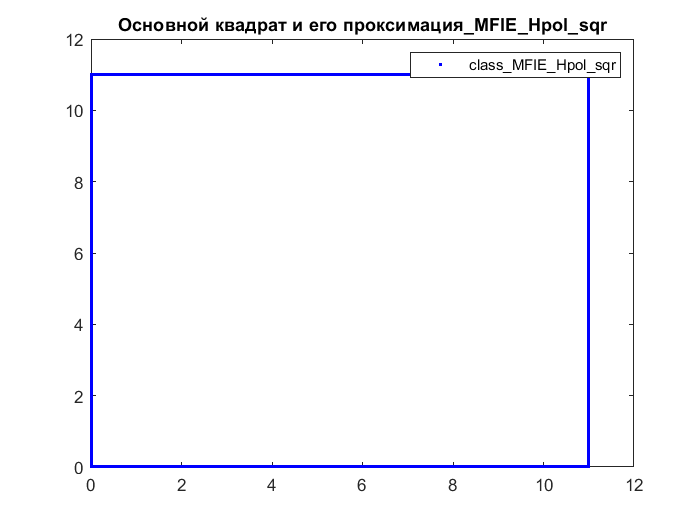

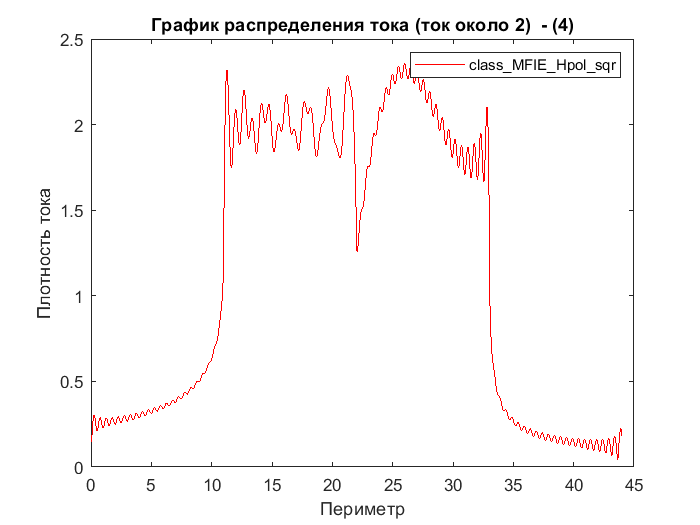

calc_4 = D_class_MIE_MFIE_sqr_H_pol(as, phi_grad);
calc_4.calculate_main_sqr(N);
calc_4.calculate_I();

Hpol_MFIE_Zmn = calc_4.Zmn;
Hpol_MFIE_Hi = calc_4.Hi;
Hpol_MFIE_I = Hpol_MFIE_Zmn\Hpol_MFIE_Hi;

#### 2.3. Графики токов (где по оси НОМЕР участка)

% n = 1 : length(EFIE_I);
% plot(n, abs(EFIE_I), n, abs(MFIE_I))
% legend('EFIE\_Epol', 'MFIE\_Epol')

#### 2.4. Вычисление CFIE

В гибсоне написано делать таок:

CFIE_Zmn = alpha*EFIE_Zmn + (1-alpha)*etta*MFIE_Zmn;

CFIE_Ei = alpha*EFIE_Ei + (1-alpha)*etta*MFIE_Hi;

НО, т.к. в обеих программах задано единичное электрчиеское поле, и опустил этта со стороны падающего поля то ДОМНОЖАТЬ НИ НА ЧТО НЕ НУЖНО!

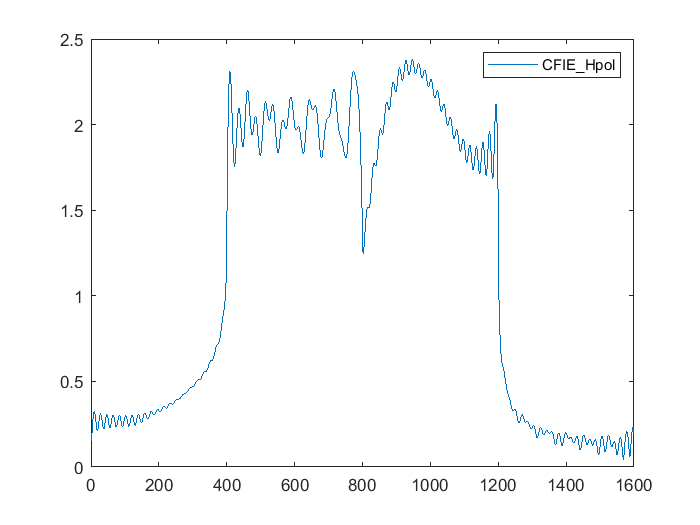

n = 1 : length(Hpol_EFIE_I);
Hpol_CFIE_Zmn = alpha*Hpol_EFIE_Zmn + (1-alpha)*etta*Hpol_MFIE_Zmn;
Hpol_CFIE_Ei = alpha*Hpol_EFIE_Ei + (1-alpha)*etta*Hpol_MFIE_Hi;

Hpol_CFIE_I = Hpol_CFIE_Zmn\Hpol_CFIE_Ei;

plot(n, abs(Hpol_CFIE_I))
legend('CFIE\_Hpol')

#### 2.5. Построение сравниельных графиков EFIE, MFIE, CFIE для эллипса

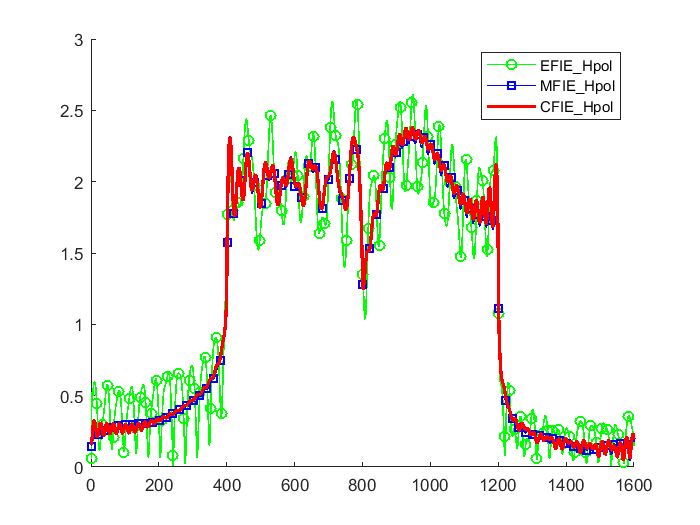

figure;
hold on;
plot(n, abs(Hpol_EFIE_I),'-go', 'MarkerIndices', 1:16:length(n), 'LineWidth', 1, 'DisplayName','EFIE\_Hpol')
plot(n, abs(Hpol_MFIE_I),'-bs', 'MarkerIndices', 1:20:length(n),'LineWidth',1, 'DisplayName','MFIE\_Hpol')
plot(n, abs(Hpol_CFIE_I), 'r', 'LineWidth', 2, 'DisplayName','CFIE\_Hpol')
legend;
hold off;

### E - поляризацяи вывод

% name_file = strcat('EFIE_Epol_', num2str(N),'.dat');
% f01 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% 
% for n=1:4*N
%     dx = as/N;
%     perimetr = dx*n - dx/2;
%     fprintf(f01,' %10.5f %10.5f\n', perimetr, abs(Epol_EFIE_I(n)));
% end
% 
% fclose(f01);

% name_file = strcat('MFIE_Epol_', num2str(N),'.dat');
% f01 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:4*N
%     dx = as/N;
%     perimetr = dx*n - dx/2;
%     fprintf(f01,' %10.5f %10.5f\n', perimetr, abs(Epol_MFIE_I(n)));
% end
% 
% fclose(f01);

% name_file = strcat('CFIE_Epol_', num2str(N),'.dat');
% f01 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:4*N
%     dx = as/N;
%     perimetr = dx*n - dx/2;
%     fprintf(f01,' %10.5f %10.5f\n', perimetr, abs(Epol_CFIE_I(n)));
% end
% 
% fclose(f01);

### H- поляризацяи вывод

name_file = strcat('EFIE_Hpol_', num2str(N),'.dat');
f01 = fopen(name_file,'w');

% за максимум Y примем значения в центре передней стороны падения


for n=1:4*N
    dx = as/N;
    perimetr = dx*n - dx/2;
    fprintf(f01,' %10.5f %10.5f\n', perimetr, abs(Hpol_EFIE_I(n)));
end

fclose(f01);

name_file = strcat('MFIE_Hpol_', num2str(N),'.dat');
f01 = fopen(name_file,'w');

% за максимум Y примем значения в центре передней стороны падения

for n=1:4*N
    dx = as/N;
    perimetr = dx*n - dx/2;
    fprintf(f01,' %10.5f %10.5f\n', perimetr, abs(Hpol_MFIE_I(n)));
end

fclose(f01);

name_file = strcat('CFIE_Hpol_', num2str(N),'.dat');
f01 = fopen(name_file,'w');

% за максимум Y примем значения в центре передней стороны падения

for n=1:4*N
    dx = as/N;
    perimetr = dx*n - dx/2;
    fprintf(f01,' %10.5f %10.5f\n', perimetr, abs(Hpol_CFIE_I(n)));
end

fclose(f01);